# Exoplanets: Discovery and Computational Methods

## Introduction

    In our solar system, there are eight planets (sorry, Pluto!) that orbit our sun. An exoplanet is defined as any planet that orbits a star outside our solar system. As of today, there have been over 4,000 experimentally confirmed exoplanet discoveries, and there are still thousands more to be experimentally verified. These confirmed exoplanets come with various questions: How are astronomers discovering these planets? What type of data and information do they receive to deduce it as an exoplanet? What is the purpose of finding these planets? This paper will answer these questions and give computational examples of this exoplanet data interpretation.

### Historical and Background information

     The potentially first observation of an exoplanet came in 1917 when astronomer Adriaan van Maanen was observing the white dwarf star now named Van Maanen 2 (Landau, 2017). When van Maanen observed the light spectrum of this dwarf star (pictured on the right), he observed high levels of heavy elements such as calcium in the star’s photosphere (outermost surface). At the time, this was interpreted as the star being an “F-type” star, which was nothing too unusual. However, these elements cannot have been created in the star and remain in the photosphere, because any element heavier than helium would sink into the star’s core. So, scientists generally accept that when a white dwarf spectrum shows high amounts of heavy metals, there must be a rocky debris belt, which could be the remnants of planetary bodies colliding and never forming planets again. So, unknowingly, the first possible evidence of an exoplanet being discovered is from 1917. The first experimentally verified exoplanet discovery occurred in 1992 when astronomers noticed that the radio “pulses” of a pulsar were occasionally slightly off than expected. However, those off-beats were still regular (Wenz, 2019). When deducing the cause of this oddity, astronomers concluded that there were two orbiting planets of masses three and four times that of earth, making it the first discovered evidence of a planet. The first exoplanet discovered around a main-sequence star was the planet 51 Pegasi B, which orbits the solar-like star 51 Pegasi. This was discovered using the radial velocity method, and examples of its computational methods will be given later in the report.

## **Methods of Discovery and Interpretation**

    There are many different methods to discover exoplanets. But, 95% of exoplanets that have been discovered and experimentally confirmed were found using the Solar Transit Method and the Radial Velocity Method. So, in this report, I will focus on these two mainstream methods. 

## **Transit Method**

    Today, the Solar Transit Method is the method of choice for experimentally discovering exoplanets. According to the NASA Exoplanet Archive, there are currently 3,444 planets that have been experimentally confirmed using the transit method. This represents over 75% of all experimentally confirmed exoplanets. Thanks to missions like the K2 mission and the Transiting Exoplanet Surveying Satellite (TESS), the transit method is the most widely used discovery method used by astronomers. Essentially, the process is regularly taking measurements of the luminosity of a star, attempting to attempt a decrease in luminosity due to a transiting exoplanet. The dip in luminosity is relatively small, on the magnitude of tenths of a percent, so using exact measurements and telescopes is essential.

### *HIP 41378*

We will be using a light curve data sample from the star HIP 41378, provided by the Kepler Mission. This data was found using the Light Curves Search in the *Mikulski Archive for Space Telescopes*, which is a NASA funded and run astronomical database. This planet has been named HIP 41378 f.

LC1 = readtable("Transit Data Planet 1.txt"); %LC1 = Light Curve 1 (for HIP 41378)
LC1.Properties.VariableNames = {'Time (BJD-2454833)' ['Corrected Light Curve (Flux)']}

LC1 = 3402×2 table
    Time (BJD-2454833)    Corrected Light Curve (Flux)
    __________________    ____________________________

          2307.6                    0.99829           
          2307.6                    0.99845           
          2307.6                     0.9985           
          2307.6                    0.99854           
          2307.6                    0.99853           
          2307.7                     0.9985           
          2307.7                    0.99844           
          2307.7                    0.99851           
          2307.7                    0.99844           
          2307.7                    0.99855           
          2307.8                    0.99852           
          2307.8                    0.99856           
          2307.8                    0.99849           
          2307.8                    0.99851           
          2307.8                

    This table gives us two columns. The first is when the data is recorded, and the second is the measured brightness of HIP 41378 at that specific time. The time measurement is measured in BJD or Barycentric Julian Day. This time measurement is standard for astronomers, where it counts the relative time with respect to the gravitational center of the solar system (barycentric center). To use this table, one would take the time in the column, and add it to the date 2454833. Using this system, the measurements take place between 2457140.55048 BJD and 2457214.41135 BJD using the first and last data points. Using a NASA tool to convert it to a calendar date, the first measurement occurred on April 29th, 2015, and the last data point was taken on July 10th, 2015. The second column is the star's flux, but it is corrected. This data must be corrected because, in the K2 mission, they had to use the thruster of the telescope to correct itself to be looking at the same spot, which affected the light emitted; hence the term "corrected."

Now, let's visualize this data. 

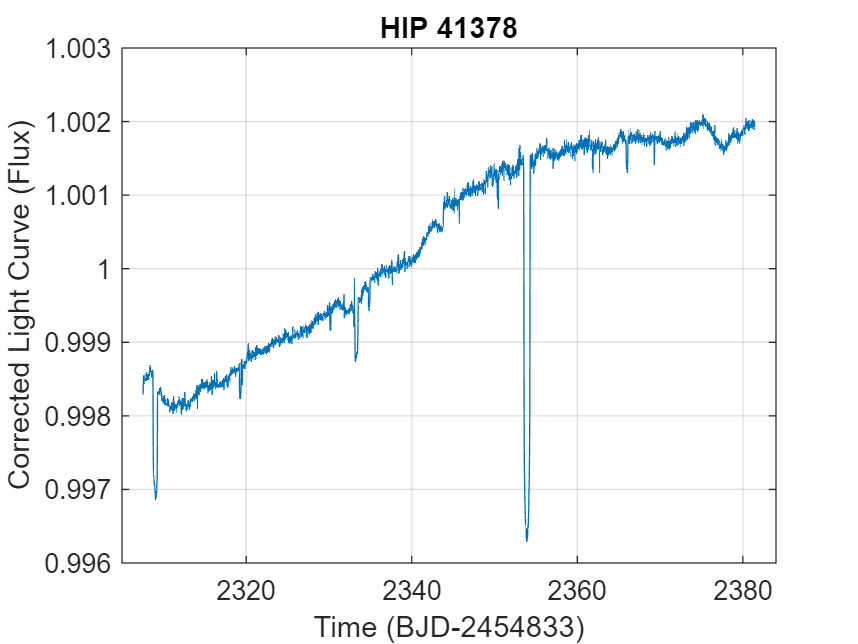

plot(LC1.("Time (BJD-2454833)"),LC1.("Corrected Light Curve (Flux)"))
%Line Plot for table LC1
xlabel('Time (BJD-2454833)'), ylabel('Corrected Light Curve (Flux)'); %Axes label
title('HIP 41378')
xlim([2305,2384]) %bounds to show whole of dataset
grid on %helpful for reference

As you can see, there is a massive dip around the BJD mark of 2355, where the light curve dips tremendously. So this visual interpretation is likely a planet moving past that is quite large, compared to the previous dips. 

Now what? How do we interpret this light curve to tell information about the transiting planet?

The depth of this light curve relates to the proportion of the radius of the transiting planet and the star it is orbiting. This is given by the equation $\textrm{Depth}={\left(\frac{R_{\textrm{Planet}} }{R_{\textrm{Star}} }\right)}^2$, which when solved for the radius of the transiting planet gives $R_{\textrm{Planet}} =R_{\textrm{Star}} \sqrt{\textrm{Depth}}$**. **The function Rpcalculator does this calculation for us.

The Radii of stars can be deduced by both luminosity and temperature*. *For the star HIP 41378, the radius has been estimated at around 1.307 Solar Radii (Vanderburg et al., 2016). To find the depth, we can look at the flux value (1.001543452) at the start of the drop at 2353.46 BJD and subtract it by the lowest point (0.996291686) in the drop at 2353.91 BJD. This calculation is Depth = 1.001543452 - 0.996291686 = 0.005251766.

Now, we can plug the radius of 1.307 and the depth of 0.005251766 into the function to return the Rplanet.

Rstar1 = 1.307;
Depth1 = 0.005251766;
Rpcalculator(Rstar1,Depth1) %Documentation of function is within the function itself

Rplanet = 4.0983e+04

ans = 4.0983e+04

We have found the planet's radius to be 40,983 miles, which is about 10.3447 times the radius of Earth. This planet is comparable in size to Jupiter, which is about 43,411 miles in radius. The experimentally determined radius of HIP 41378 f is 0.91 ± 0.125 times the size of Jupiter (Vanderburg et al., 2016), and our calculation falls within that margin of error.

Using only a single transit, we can deduce the radius of an orbiting planet. Next, we can see what we can conclude using multiple repeated transits of a single planet.

### *WASP-47*

    Now, we can look at another set of data, from the star WASP-47, obtained in the Mikulski Archive for Space Telescopes. This time, we will use the solar transit data to find the radius of the planet and use the data to determine the orbital period and orbital radius of the planet. But, first, let's import the data. 

LC2 = readtable("TD2.txt"); %LC2 = Light Curve 2 (for WASP-47)
LC2.Properties.VariableNames = {'Time (BJD-2454833)' 'Corrected Light Curve (Flux)'}

LC2 = 2913×2 table
    Time (BJD-2454833)    Corrected Light Curve (Flux)
    __________________    ____________________________

          2146.5                     1.0004           
          2146.5                     1.0003           
          2146.5                     1.0002           
          2146.6                     1.0002           
          2146.6                     1.0002           
          2146.6                     1.0002           
          2146.6                     1.0001           
          2146.6                     1.0002           
          2146.7                     1.0003           
          2146.7                     1.0003           
          2146.7                     1.0001           
          2146.7                     1.0002           
          2146.7                    0.99989           
          2146.8                    0.99992           
          2146.8                

    The time here is still in BJD or Barycentric Julian Days. These measurements occur between the times 2456979.45248 BJD and 2457046.26406 BJD using the first and last data points. Using a NASA tool to convert it to a calendar date, the first measurement occurred on November 17th, 2014, and the last data point was taken on January 23rd, 2015. Now, we can make a visualization of the data.

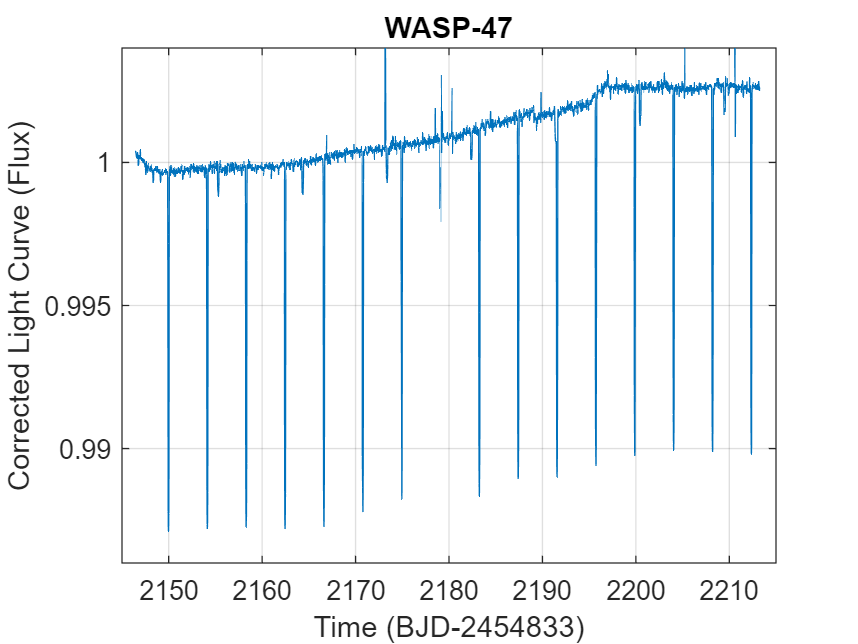

plot(LC2.("Time (BJD-2454833)"),LC2.("Corrected Light Curve (Flux)"))
%Line Plot for table LC2
xlabel('Time (BJD-2454833)'), ylabel('Corrected Light Curve (Flux)'); %Axes label
title('WASP-47')
ylim([0.986,1.004]) %setting the limit in height removes the outlier data
xlim([2145,2215])
grid on %helpful for reference

    It is quite clear that a planet is passing through this star quite frequently. Using the graph, we can deduce this planet's orbital period (how often it makes a revolution around its star). Using an average of the gap between each drop in flux, the orbital period is estimated at about 4.159 days. Now, we will use the same function Rpcalculator to deduce the planet's radius. Astronomers have estimated the radius of this star to be about 1.14 times the radius of our sun (Hellier et al., 2012). Now, we can find the average depth between the drops. Taking the average of the first five transits, we get an average depth of .0116946. Now, we can deduce the radius.

Rstar2 = 1.14;
Depth2 = .0116946;
Rpcalculator(Rstar2,Depth2) %Documentation of function is within the function itself

Rplanet = 5.3343e+04

ans = 5.3343e+04

This deduces the radius of this planet to be about 53,343 miles, or about 1.229 times the size of Jupiter. This radius is staggering, considering that it is an enormous planet with a radius 1.229 times that of Jupiter, that orbits its host star about every four days, compared to the twelve-year orbital period of Jupiter in our solar system itself. 

Now, we can find the orbital radius of this planet with its star. As is previously denoted, Kepler's third law states that $\frac{T^2 }{R^3 }=K$. What is this constant K? We can derive this constant using both Newton's Law of Gravity and centripital force equations.  Newton's Law of Gravity states that $F=\frac{\mathrm{GMm}}{r^2 }$, and centrepital forces are denoted by $F=\frac{{\mathrm{mv}}^2 }{r}$. Setting these two forces equal to each other and solving for $v^2$, $v^2 =\frac{\mathrm{GM}}{r}$. We also know that $v=\frac{d}{t}=\frac{2\pi r}{T}$. Substituting this into the equation for $v^2$, we get ${\left(\frac{2\pi r}{T}\right)}^2 =\frac{\textrm{GM}}{r}$. Solving for $T^2$, we get that $T^2 =\frac{4\pi^2 }{\textrm{GM}}r^3$. Dividing by $r^3$, we get $\frac{T^2 }{r^3 }=\frac{4\pi^2 }{\mathrm{GM}}$, which is equal to the constant K. So, I have made another function to determine the constant, given the star's mass. Scientists have deduced that the mass of WASP-47 is about 1.08 times the mass of the sun (Hellier et al., 2012).

StarMass = 1.08;
Kcalculator(StarMass) %Documentation of function is within the function itself

Kconstant = 2.7552e-19

ans = 2.7552e-19

Using this constant (given with units of $\frac{s^2 }{m^3 }$), we can solve for the orbital radius in meters, when the orbital period is given in seconds. The period of 4.159 days is equal to about 359346 seconds.

Kconstant = 2.7552.*(10^-19);
OrbitalT = 359346;
ORcalculator(Kconstant,OrbitalT) %Documentation of function is within the function itself

OrbitalRadius = 7.7675e+09

ans = 7.7675e+09

    This answer is $7\ldotp 7675*{10}^{9\;}$ meters, or 7,767,500 km. This orbit is only 5.192% of Earth's orbital radius, which is 149,597,000 km comparatively.  This planet has been named WASP-47b, and we can compare our calculated data to the averaged measurements over multiple professional studies and surveys. The radius of the planet is about 1.127 times the size of Jupiter (Vanderburg et al., 2017), which is relatively comparable to the size we calculated of 1.229 times the radius of Jupiter with a 9.05% error. Our calculation of the orbital radius is almost exactly accurate in AU (1 AU = orbital radius of Earth). We calculated from the orbital period that the orbit is about 0.05192 AU. The experimentally obtained orbital radius is 0.0520 ± 0.0006 AU (Hellier et al., 2012). That is an incredibly accurate approximation given roughly 80 days of approximation in the dataset LC2. 

From a simple periodic light curve graph, we could deduce the radius, orbital period, and orbital radius of a planet 870 light-years away from Earth.

## Radial Velocity (Doppler Spectroscopy)

     Doppler Spectroscopy or Radial Velocity was the first method used to discover an exoplanet. This method relies on the mutual gravitational pull of a planet-star system. Due to the planet's relatively small force of gravity, the star has a small orbital radius (sometimes called a 'wobble') around the gravitational center of the system. From our distant point of view, these slight movements cause a shift in the star's light spectrum. When the star is moving away from us, the light changes towards the red (longer) wavelengths, and when it moves towards us, the wavelengths become bluer (shorter) due to the Doppler Effect (hence Doppler Spectroscopy). Using this change in wavelength can then be used to calculate the radial velocities of the star.

## *51 Pegasi*

      We will be taking radial velocity data from the Lick Observatory in CA, where they used the Hamilton Echelle Spectrograph to observe the Doppler shift data in the star 51 Pegasi (Marcy et al., 1997). As mentioned before, the planet orbiting 51 Pegasi, denoted as 51 Pegasi b, was the first planet discovered to be orbiting a main-sequence star. As the researchers who experimentally discovered it stated in the introduction, " If confirmed, the discovery of the first planet orbiting a solar-type star marks a watershed event in science" (Marcy et al., 1997). When writing in 1997, they were unsure whether their discovery would withstand scrutiny. Little did they know at the time, their finding would be confirmed and would start a revolution of planet-hunting across the scientific community. 

RV1 = readtable("51PegasibRVData.txt"); %RV1 = Radial Velocity Data for 51 Pegasi
RV1.Properties.VariableNames = {'Time (JD-2450000)' 'Velocity (m/s)' 'Error (m/s)'}

RV1 = 111×3 table
    Time (JD-2450000)    Velocity (m/s)    Error (m/s)
    _________________    ______________    ___________

         2.6736              -40.87            3.3    
         2.8087              -46.96            3.6    
         2.9598              -47.39            4.5    
         3.6269              -19.85            2.9    
         3.7327              -13.47            2.6    
         3.9008              -5.782              3    
         4.6075               49.41            2.2    
         4.7843               58.66            2.5    
          4.907                63.2            3.2    
          5.605                45.6            2.7    
         5.9254               17.88            3.3    
         11.644               -45.5            4.7    
         11.838              -38.98            4.9    
         12.636               27.27            5.2    

    These measurements were taken between the dates 2450002.67365 BJD and 2450326.8960 BJD. Converting these to standard dates, the measurements were taken between October 12, 1995, and August 31, 1996. The second column is the Doppler velocities of the star 51 Pegasi, measured over 324 days. The third column depicts the estimated error bars in the velocity measurements. Let's visualize this data.

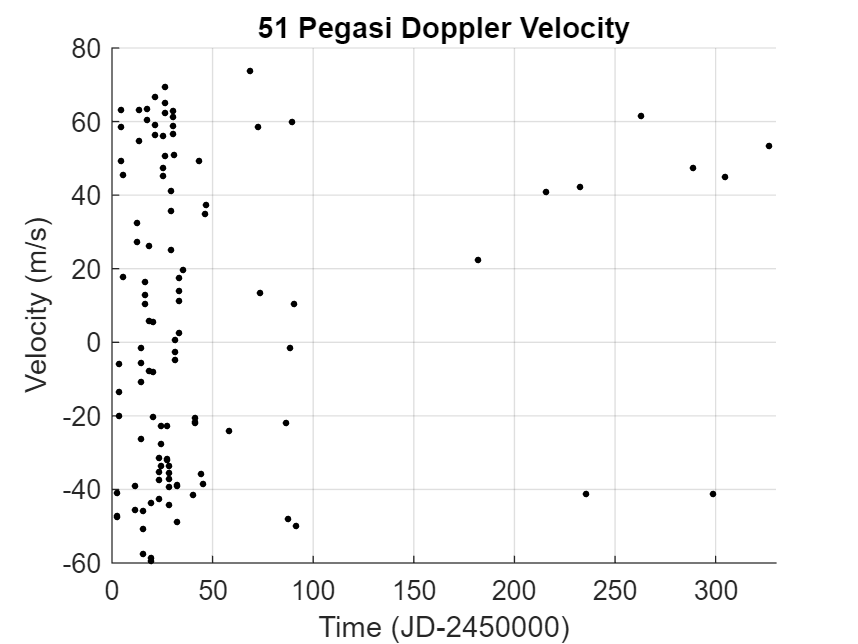

scatter(RV1.("Time (JD-2450000)"),RV1.("Velocity (m/s)"),6,"black","filled")
grid on
title('51 Pegasi Doppler Velocity')
ylabel('Velocity (m/s)'), xlabel('Time (JD-2450000)');
xlim([0,330])

    When doing an initial scatterplot, it seems as if the data has no correlation. But, we can look more closely at the nature of the measurement to find a line of best fit. Because this velocity is the periodic motion of an orbiting system, the data correlates quite well to a sinusoidal curve. Now, we can take these points, add the error bars, and fit them behind the Keplerian fit sinusoidal curve.

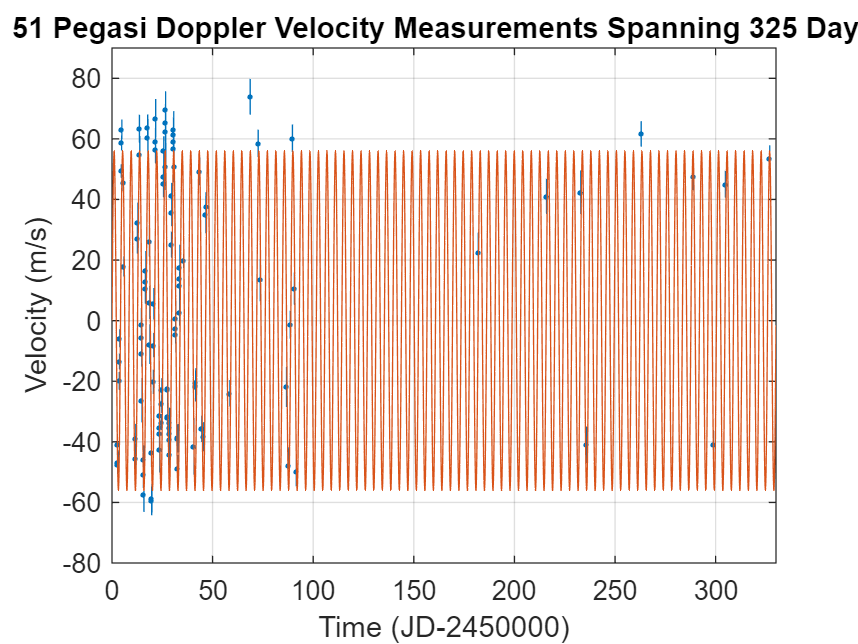

clf
x = RV1.("Time (JD-2450000)");
y = RV1.("Velocity (m/s)");
error = RV1.("Error (m/s)");
t=0:0.01:330; %Parameter for Keplerian curve
e = 56.04*sin(1.485035525*t); %1.485035525 is the wave number, or 2(pi)/T = 2(pi)/4.231
% e = Keplerian curve of best fit, 56.04 m/s = recorded average amplitude
errorbar(x,y,error,'vertical','.','MarkerSize',6,'CapSize',0)
% errorbar = scatterplot with error bars
ylim([-80,90])
xlim([0,330])
ylabel('Velocity (m/s)'), xlabel('Time (JD-2450000)');
grid on
title('')
hold on % hold on allows for the next plot function to occur on the same graph
plot(t,e) %Plotting the Keplerian fit behind the datapoints
title('51 Pegasi Doppler Velocity Measurements Spanning 325 Days')
hold off

    Now that there is a sinusoidal curve behind the data points, the points correlate much better. However, unless the figure is detached from the window and enlarged, it is hard to tell from first glace that the data correlates well. This is due to the high amplitude nature along with the short period of the Keplerian fit. But, we can manipulate the time measurements to correlate with a scalar from 0-1 of the phase that it is in to show each Kepler oscillation on top of one another. 

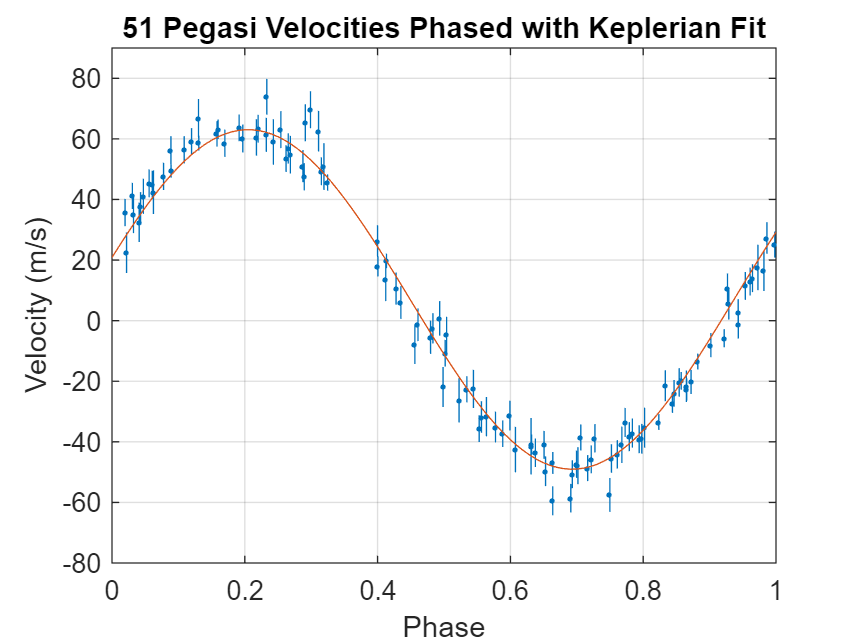

clf
x = RV1.("Time (JD-2450000)");
y = RV1.("Velocity (m/s)");
error = RV1.("Error (m/s)");
b = mod(RV1.("Time (JD-2450000)"),4.231)./4.231; %b becomes the modified time measurements in phase.
% each b value was found by taking the remainder the time/period caclulation,
% dividing by the period again, to get its proportion of the period from 0-1.
t=-0:0.01:1; %Parameter for ONE period of a Keplerian curve
e = 56.04*sin(2.05*(pi)*t+0.25)+7; 
% e = Keplerian curve of best fit
errorbar(b,y,error,'vertical','.','MarkerSize',6,'CapSize',0)
% errorbar = scatterplot with error bars
title('51 Pegasi Velocities Phased with Keplerian Fit')
ylim([-80,90])
ylabel('Velocity (m/s)'), xlabel('Phase');
grid on
hold on % hold on allows for the next plot function to occur on the same graph
plot(t,e) %Plotting the Keplerian fit behind the datapoints
hold off

     As seen in the figure, when the data is put into only one phase, it perfectly fits the curve. This shows that the periodicity of the moving star is maintained throughout nearly a year of measurements. Stars do not just randomly move with incredibly predictable periodic velocities unless something else is tugging on them. There is only one star in this system, so nothing else could be tugging on the star causing this periodic motion besides an exoplanet (especially with the 'unknown' mass causing this stellar motion being on the order of planetary size). Now, using the data extrapolated from the graph, we can calculate some planet's characteristics. We will calculate the orbital radius (semi-major axis), orbital velocity, and mass of the exoplanet. The star's mass has been determined to be about 1.11 Solar Masses (Fuhrmann et al., 1997).

SM51Pegasi = 1.11; %Solar mass of 51 Pegasi
Kconstant2 = Kcalculator(SM51Pegasi) %Documentation of function is within the function itself

Kconstant = 2.6807e-19

Kconstant2 = 2.6807e-19

Using the Keplerian constant in the equation $\frac{T^2 }{R^3 }=K$, we can calculate the orbital radius using the function ORcalculator.

OrbitalT2 = 365558.4;
OR51Pegasi = ORcalculator(Kconstant2,OrbitalT2) %Documentation of function is within the function itself

OrbitalRadius = 7.9288e+09

OR51Pegasi = 7.9288e+09

    According to our data and calculations, the orbital radius of the exoplanet is approximately 7,928,800 kilometers, which is about 0.05286 AU. This calculation falls within the generally accepted measurement of 0.0527 ± 0.0030 AU (Marcy et al., 1997). Taking the orbital radius and the mass of the star, we can deduce the orbital velocity using the previously derived equation $v^2 =\frac{\textrm{GM}}{r}$, which is then reduced to $v=\sqrt{\frac{\textrm{GM}}{r}}$. This mathematical calculation is within the function RVcalculator.

RV51PegasiB = RVcalculator(SM51Pegasi,OR51Pegasi) %Documentation of function is within the function itself

RadialVelocity = 1.3628e+05

RV51PegasiB = 1.3628e+05

    This calculation of $1\ldotp 3628*{10}^{5\;} \frac{m}{s}$ can then allow us to apply conservation of momentum rules to deduce the mass of the exoplanet. The derivation sets the momentum of the star equal to the momentum of the exoplanet, or $P_S =P_P$. This can further be reduced to $M_{\textrm{star}} v_{\textrm{star}} =m_p v_p$. When solving for the velocity of the planet, we get $m_p =\frac{M_{\textrm{star}} v_{\textrm{star}} }{v_p }$. Now, the mathematical calculation in the function MPcalculator can complete this equation.

Vstar = 56.04; %Given as average of peak velocity, in m/s, also seen as the amplitude of the Keplerian curve
MPcalculator(RV51PegasiB,SM51Pegasi,Vstar) %Documentation of function is within the function itself

MassPlanet = 9.0788e+26

ans = 9.0788e+26

    The answer that we arrive at is $9\ldotp 0788*{10}^{26\;} \textrm{kg}$ or about 0.47833 times the mass of Jupiter. The scientifically calculated mass of the planet is 0.46 ± 0.3 Jupiter masses (Martins et al., 2015). Our calculation falls well within the scientifically accepted result.

## **Why Find Exoplanets?**

    The history of the human race is one of discovery and exploration. Humans have explored every bit of land on earth, touched the moon, and had technology on other planets. We are not done exploring our solar system at all, for technological missions to the outer planets, moons of Jupiter and Saturn, and manned missions to Mars are already being planned. But, once the exploration of the solar system has been exhausted, what is next? The answer is discovering and exploring planetary systems and bodies beyond our solar system. Although taking our technology or people to these systems is far too advanced for our stage of technology, it might not be in the future. Exoplanet discovery is the next frontier of human exploration.

    Before 1992, we had eight planets to study, and that was it. We had a minimal view of how solar systems arose and planets formed. Now, with over 4,500 exoplanets discovered, we have exponentially more knowledge about these areas. If we cannot find evidence of life in our solar system, the next place to look is outside, to exoplanets that could harbor life. Discovering life outside our world could very well be the most significant singular discovery in human history, and alter the course of history forever. So, exoplanet discovery is the perfect method for our human desire for exploration to be fulfilled. We are at the forefront of this exploration, and much more technology is available than ever before. But, in the future, our technology will be so advanced that those studying exoplanets today will be pioneers of the future of space exploration. 